## Parameter Analysis

uses the **minCOT.m** function to analyze parameters of interest:

- **forward speed (xdot_target)**

- **leg inertia (I)**

- **spring constant (k)**

- **damping constant (c)**

### **Forward Speed**

% add necessary paths
addpath('functions/multiOpt');
addpath('functions/sharedFuncs');
addpath('warmStartTemplates')

% some constants
k = 735;
c = 2.8;
I = 1.5e-4;

running_COTs = [];
hopping_COTs = [];
speeds = [];

for speed=2:0.5:4
    running_COTs = [running_COTs, minCOT('r',speed, k, c, I)];
    hopping_COTs = [hopping_COTs, minCOT('h', speed, k, c, I)];
end

using warm start template

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


using warm start template

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


using warm start template

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


using warm start template

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


using warm start template

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


using warm start template

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


using warm start template

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


using warm start template

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


using warm start template

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


using warm start template

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


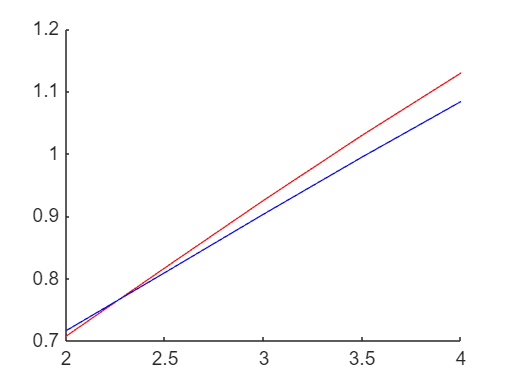

close all;
hold on;
plot(2:0.5:4, running_COTs, 'r-');
plot(2:0.5:4, hopping_COTs, 'b-');
hold off;

rmpath('functions/multiOpt');
rmpath('functions/sharedFuncs');